# はじめに

## 制御とは

制御とは、一言で表現すると、制御対象の値を目標値に近づける、または可能なら一致させることを意味する。例えば、Fig.1のように、法定速度が50km/hとなっている道路にて、法定速度通り自動車を走行させる場合を考える。

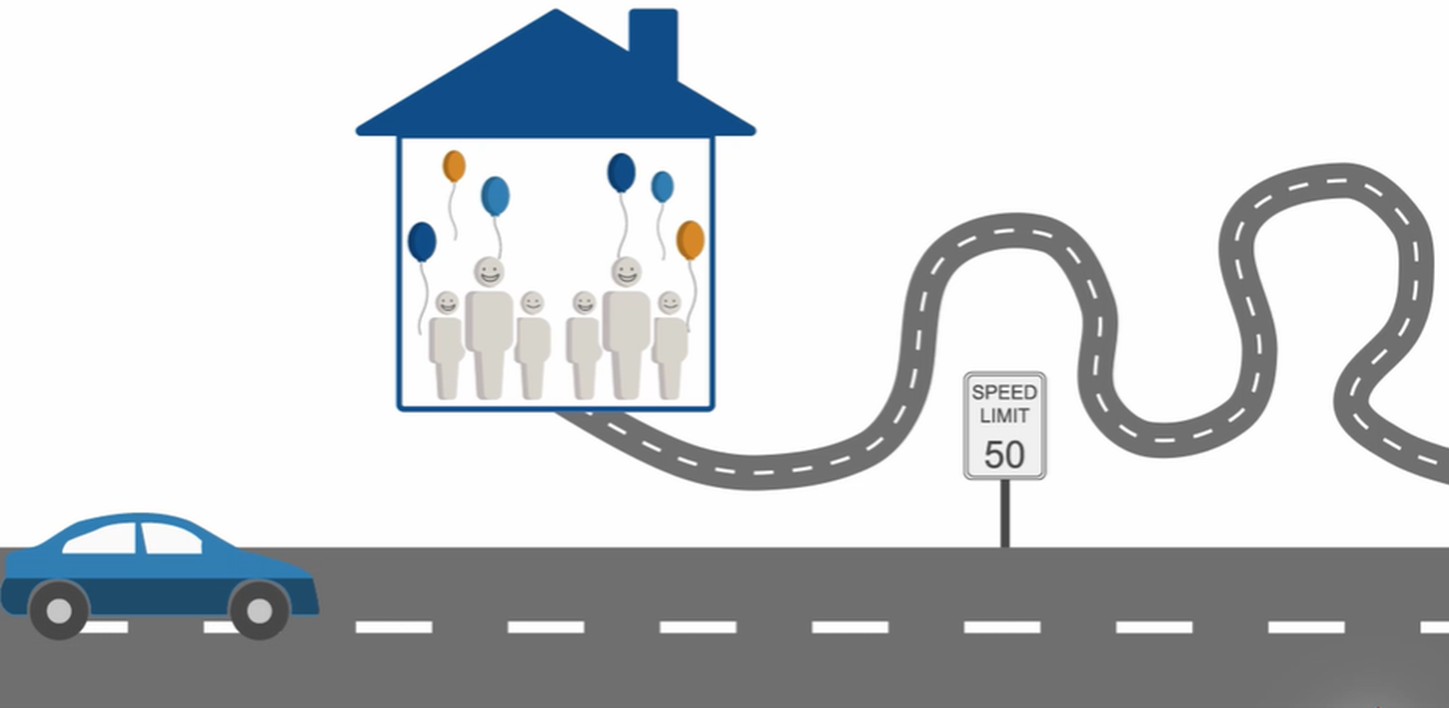

Fig.1 道路を走行する自動車

一般的な運転操作として、次のような操作が考えられる。速度0の状態からスタートする場合は、まずアクセルを踏み、自動車を加速させる。時間が経過して速度が目標値（50km/h）に近づくにつれて、アクセルを踏む量を減らしていく。自動車の速度が目標速度に一致した所でアクセルを離す。ただし、自動車は走行中に抵抗を受けるため、常にある程度のアクセルを踏み続けないと、速度を維持させることができない。

従って、Fig.2のような動作結果が得られる。

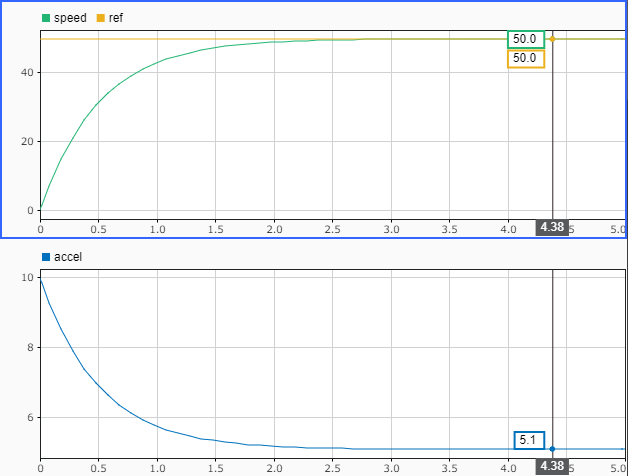

Fig.2 自動車を50km/hで走行させる制御を行った結果

Fig.2の「ref」は目標速度、「accel」はアクセル量、「speed」は自動車の速度である。

この操作を行う際、人間は以下の処理を繰り返し行っていると考えられる。

- 今の速度と目標値との差分を見る

- アクセル踏み込み量を決め、踏み込む

- 踏み込んだ後、速度を再度確認する

この処理の流れをブロック線図で記述すると、Fig.3のようになる。

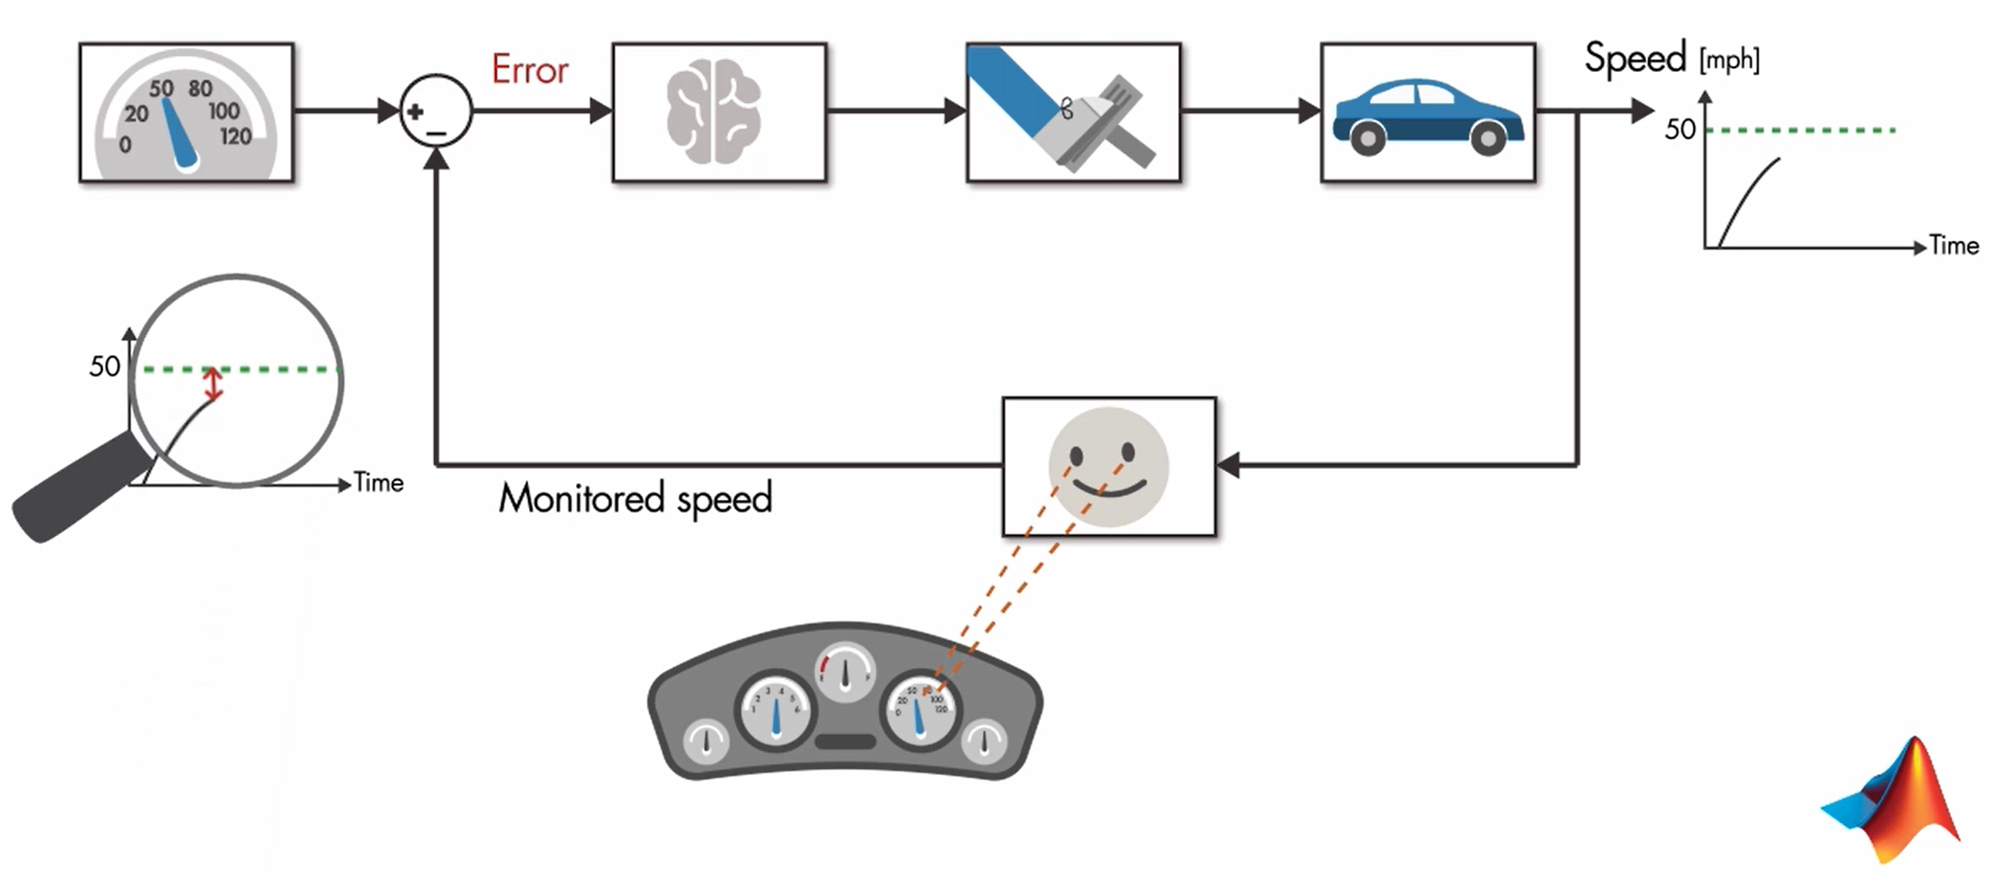

Fig.3 自動車のフィードバック制御ループ

これを一般的に「フィードバック制御」と呼ぶ。操作した結果を常にフィードバックして、次の操作を求めていることから、そのように呼ばれている。

フィードバック制御は制御の基本型であり、古典制御と言われるPID制御から、先進制御のモデル予測制御も含め、あらゆる制御則がこの型を基本としている。

## フィードフォワード制御

一方で、「フィードフォワード制御」という手法も存在している。

先程の自動車の例で、もし初めからアクセル踏み込み量と、発生する自動車の加速度の関係が分かっており、アクセル操作に十分習熟している場合には、決められた操作で0から50km/hにすることも可能である。

例えば、Fig.4のように操作をする。

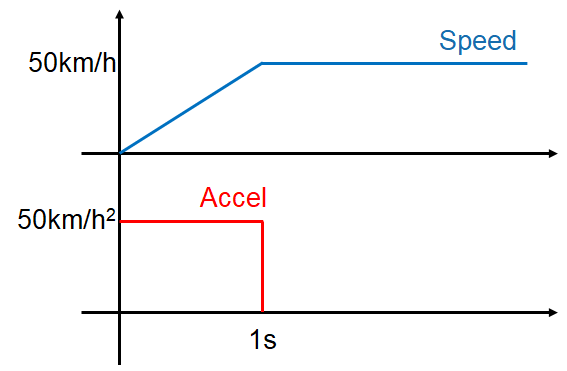

Fig.4 フィードフォワード操作

1秒間、50$\textrm{km}/{\mathrm{h}}^2$の加速度を与え、その後加速度を0にする。その結果、速度は50km/hとなる。この時、自動車の走行速度は全く見ていない。従って、この操作はフィードバック制御ではない。

このように、フィードバックを伴わない制御型を「フィードフォワード制御」と呼ぶ。

フィードフォワード制御は、現実にはそれ単体で用いられることは稀である。なぜなら、現実世界では以下のような現象が発生するため、完璧な操作を行うことができないためである。

- 制御対象のモデルに誤差がある

- 計測できない外乱が加わることがある

- 計測ノイズが存在していることがある

人間が自動車を運転する例で言うならば、目隠し状態で0から50km/hまで加速し、その後50km/hで維持する、という運転方法がフィードフォワード制御である。現実世界ではいかに困難であるか、想像できることと思われる。

ほとんどの場合、フィードフォワード制御はフィードバック制御の補助として用いられる。その制御対象の固有のダイナミクスが予め分かっている場合に、それを考慮したオフセット入力を作るためにフィードフォワード制御を用いることができる。

### Task 1

同じ制御対象に、フィードバック制御とフィードフォワード制御を適用し、その動作の違いを確認する。このセクションのスクリプトを実行すること。

'FOA_fb_ff_comp.slx'を開き、フィードバック制御とフィードフォワード制御のブロック線図の違いを確認する。

model_name = 'FOA_fb_ff_comp';
open_system(model_name);

モデルを実行して、結果を比較する。

sim(model_name);
FOA_fb_ff_plot_in_SDI;

ここで、モデル内の'dist_fb'ブロック、'dist_ff'ブロックの値を変更し、再度シミュレーションを実行し、結果を確認する。これらのブロックは、それぞれの制御システムに入力される一定値外乱である。

|　[進む（UAVのホバリング）](matlab:(proceed_live_page('UHG_control_UAV.mlx')))

*Copyright 2021 The MathWorks, Inc.*